# IFDIFF - A Matlab Toolkit for ODEs with State˗Dependent Switches

The software package `IFDIFF` deals with the solution and algorithmic generation of sensitivities in ordinary differential equations with implicit (state-dependent) non-differentiabilites (“switches”) in the right-hand side that is given as Matlab program code with non-differentiable operators such as `min`, `max`, `abs`, `sign`, as well as `if`-branching. `IFDIFF` automatically generates only necessary switching functions, outputs them as Matlab code, and detects switching points accurately up to machine precision.

`IFDIFF` handles multidimensional state and parameter vectors and can be transparently used in existing code, as it generates `sol` solution structures compatible to the `MATLAB` ode solvers. No modifications to the right hand side or manual processing are necessary. A single preparation call is sufficient.

In the `PErFDiff` project, the existing implementation is to be further developed and extended for Filippov systems.

For a more in-depth explanation of the package please visit [`IFDIFF`](https://andreassommer.github.io/ifdiff/).

## A first example and demonstration of the `IFDIFF` library

The first thing to do when solving switched ODEs with `IFDIFF` is to define the Initial value problem (IVP). Lets take a look at the following canonical example ODE:


$$\dot{x} = f(t,x,p) = \pmatrix{f_1(t,x,p) \cr f_2(t,x,p)} \\ \\

f_1(t,x,p) = 0.01 \cdot t^2 + x_2^3 \hspace{20pt} f_2(t,x,p) = \begin{cases} 
0 & \text{if} & x_1 < p \\ 5 & \text{if} & p \leq x_1 < p +0.5 \\ 0 & \text{if} & x_1 \geq p + 0.5 \end{cases}$$


With the initial value:

$x(0) = (1,0)^T \hspace{20pt} \text{and the paramteter} \hspace{20pt} p=5.437$.

The **Right-Hand-Side** (RHS) is stored in a separate `MATLAB` function file called `canonicalExampleRHS.m`. It can be found [here](matlab:open('./canonicalExampleRHS.m')). and looks like:

type canonicalExampleRHS.m


function dx = canonicalExampleRHS(t,x,p)

    dx = zeros(2,1);
    dx(1) = 0.01 * t.^2  +  x(2).^3;

    if x(1) < p(1)
        dx(2) = 0;
    else
        if x(1) < p(1) + 0.5
            dx(2) = 5;
        else
            dx(2) = 0;
        end
    end
end





### Initialization:

The initial values, the time interval, the parameter(s) as well as the integrator (here Runge Kuta 45) can be defined as follows:

clear;
initPaths();

integrator = @ode45;
t0 = 0;
tf = 20;
timeinterval = [t0,tf];
initstates   = [1  0 ];
p            = 5.437;

### Integration-Options and Datahandle:

Next, we define the integrator options, refer the file name of the RHS and prepare the **Datahandle **using the function `prepareDatahandleForIntegration()`.

odeoptions = odeset( 'AbsTol', 1e-20, 'RelTol', 1e-12);
filename = 'canonicalExampleRHS';
dhandle = prepareDatahandleForIntegration(filename, 'integrator', func2str(integrator), 'options', odeoptions);

### Integration:

Now, we can solve our first ODE with `IFDIFF`. The `solveODE()` function takes care of this and is called with the datahalnde as well as all previously defined parameters and states of the IVP.

sol_ifdiff = solveODE(dhandle, timeinterval, initstates, p);

### Naive Integration:

For demonstration purposes we want to compare this result to the naive approach when using `MATLAB` integration.

sol_matlab = integrator(@(t,x) canonicalExampleRHS(t,x,p), timeinterval, initstates, odeoptions);

### Accurate Euler Integration:

As it is common practice, we check the results against an Euler integration with small stepsize.

N_euler =3000000;
[T, Y_euler, Y_matlabsolver, Y_ifdiff] = run_accurate_euler(N_euler, t0, tf, initstates, p, @canonicalExampleRHS, sol_matlab, sol_ifdiff);

Note that the `sol` structure returned by `solveODE` is an augmented version of the solution structures returned by Matlab’s very own integrators (see [Matlab documentation](https://de.mathworks.com/help/matlab/ref/deval.html#bu7iw_j-sol)), and can thus be evaluated using `deval`. That means, `IFDIFF` can be used transparently within existing code!

## Solutions

### Plot the Solution-Trajectories of all Integrators:

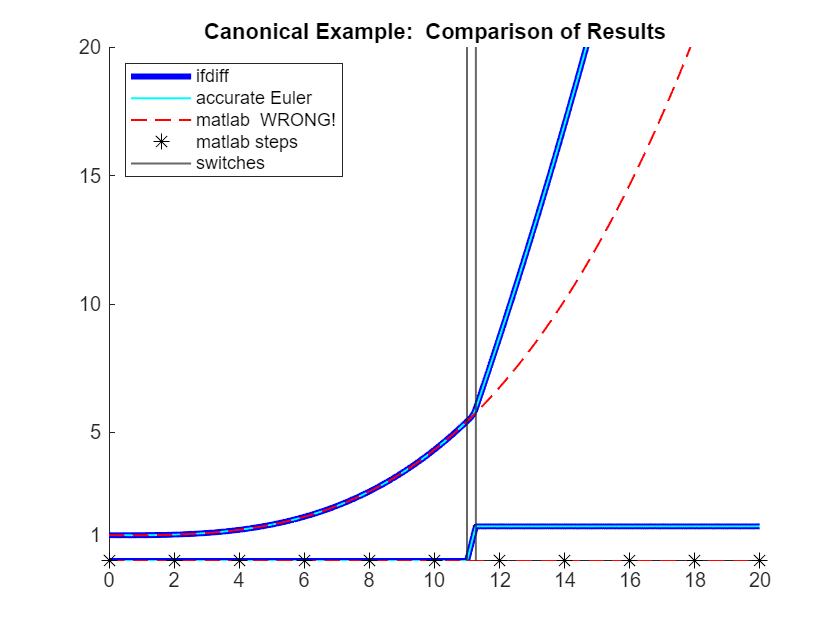

plot_canonical_comparison(544, tf, T, Y_ifdiff, Y_euler, Y_matlabsolver, sol_matlab, sol_ifdiff, 20);

### Plot the Difference-Trajectories of the the Integrators compared to `IFDIFF`

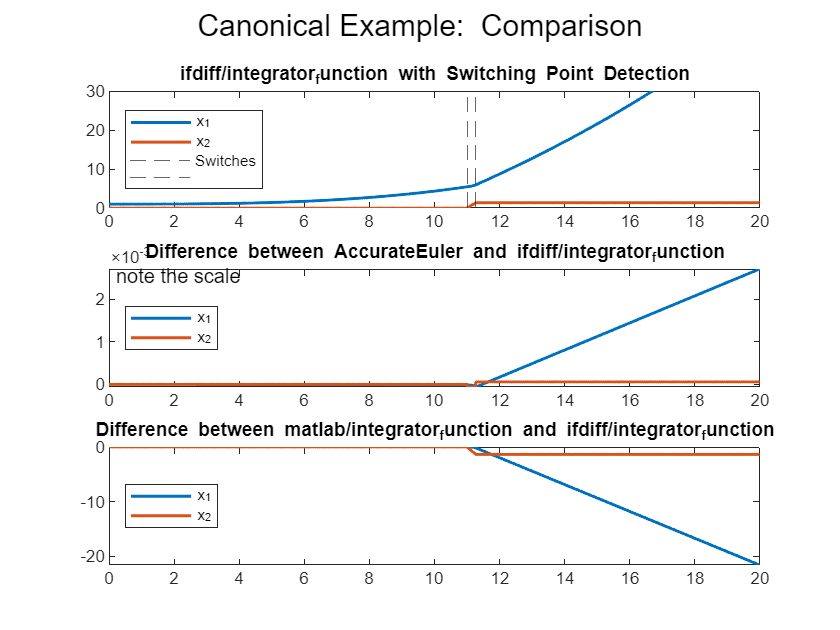

plot_comparison_subplots(545, tf, t0, T, Y_ifdiff, Y_euler, Y_matlabsolver, sol_ifdiff, @integrator_function);